# Create Machine Learning Models of Design Space Results for Suspension Model

Updated: now using options for model training

The script requires Statistics and Machine Learning Toolbox, and Deep Learning Toolbox

status_ml = license('test','Statistics_Toolbox');
status_dl = license('test','Neural_Network_Toolbox');
if ~status_ml
    error('The rest of the script cannot be executed. You need to have a license of the Statistics and Machine Learning Toolbox to proceed.')
elseif status_ml && ~status_dl
    warning('Only the machine learning part of the script will be executed. Training using deep learning toolbox will be skipped.')
end

## Part 1. Load DOE Data

Read the parameter table containing information about the input variables, including which ones were included in the design space and which were set to base values

addpath(genpath('../'))

parTableFilename = "parTableVal_trimSensitivity.mat";
load(parTableFilename,"parTableVal_trim");
parTableVal = parTableVal_trim;

Read the run table containing the input variables for all runs

runTableFilename     = "doeRunTable.mat"; % Load the Latin Hypercube results with 1000 runs
resultsTableFilename = "doeResultsTable.mat";
% runTableFilename = "sobolDoeRunTable10.mat"; % Load one of the sobol iterations, each iteration file includes previous iterations
% resultsTableFilename = "sobolDoeResultsTable10.mat";

load(runTableFilename,"runTable");
load(resultsTableFilename,"resultsTable");

Combine the data into a single table for machine learning on the variables included in the design space, and all 3 response variables.

% Capture the variable names and descriptions (full parameter names)
inputVars = string(parTableVal.Label);
inputVars = inputVars(parTableVal.Use);
inputDescriptions = string(parTableVal.Parameter);
inputDescriptions = inputDescriptions(parTableVal.Use);
responseVars = string(resultsTable.Properties.VariableNames);

numInputs = numel(inputVars);

Apply constraints to inputs and responses. 

inputTable = runTable(:,inputVars);

filterInputConstraints = false;
% if filterInputConstraints
%     % define constraint
%     idx = ((inputTable.HP_A1_Ro_Inbz - inputTable.HP_A1_Ro_Outz)>=-0.05);
%     inputTable = inputTable(idx,:);
%     idx = ((inputTable.HP_A1_Ro_Inbz - inputTable.HP_A1_Ro_Outz)<=0.04);
%     inputTable = inputTable(idx,:);
% end

Specifically, brake Distance is not recommended as a response variable, thus is removed here for downstream activities

filterResponseLimits = true;
if filterResponseLimits % 12/04/2024 - Updated with new response names
    % Use some hard limits to remove points out of bounds
    % dataTable = dataTable(dataTable.RideMetric<0.8,:);
    % dataTable = dataTable(dataTable.RollMetric<0.25,:);
    % dataTable = dataTable(dataTable.BrakMetric<28,:);
    responseVars = responseVars(1:2);
    numResponses = numel(responseVars);
    resultsTable = resultsTable(:,responseVars);
end

Create the data table

dataTable = [inputTable resultsTable];

Split into training (80%) and test data (20%)

cv = cvpartition(height(dataTable), HoldOut=0.2);
idx = training(cv);
trainingTable = dataTable(idx,:);
testTable = dataTable(~idx,:);

For deep learning models, convert the data to a format that the `trainnet` function supports. Convert the predictors and targets to numeric and categorical arrays, respectively. For feature input, the network expects data with rows that correspond to observations and columns that correspond to the features. If your data has a different layout, then you can preprocess your data to have this layout or you can provide layout information using data formats. For more information, see [Deep Learning Data Formats](https://www.mathworks.com/help/deeplearning/ug/deep-learning-data-formats.html).

XTrain = table2array(trainingTable(:,inputVars));
TTrain = table2array(trainingTable(:,responseVars));

XTest = table2array(testTable(:,inputVars));
TTest = table2array(testTable(:,responseVars));

## Part 2. Analyze the Data

Create plots of the input and response data, to understand the design space and results

### Show the Data Table with Sparklines and Stats

In the Live Editor, right click on the table to display these

dataTable

dataTable = 826×12 table
    HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy    RideMetric    RollMetric
    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    __________    __________

         0.175            0.155            -0.35              0.4              0.1            0.656              0.1             0.25                 0            0.55 

### Plot Responses

Show distribution of response values

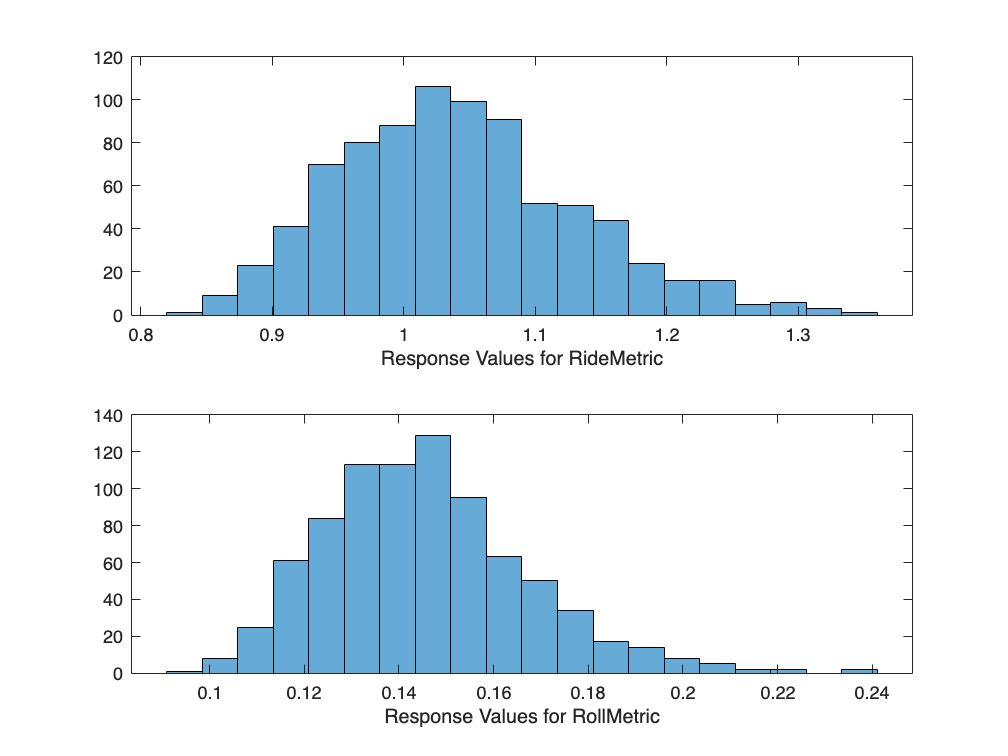

figure;
for i = 1:numResponses
    response = responseVars(i);
    subplot(2,1,i)
    histogram(dataTable.(response),20);
    xlabel("Response Values for " + response);
end

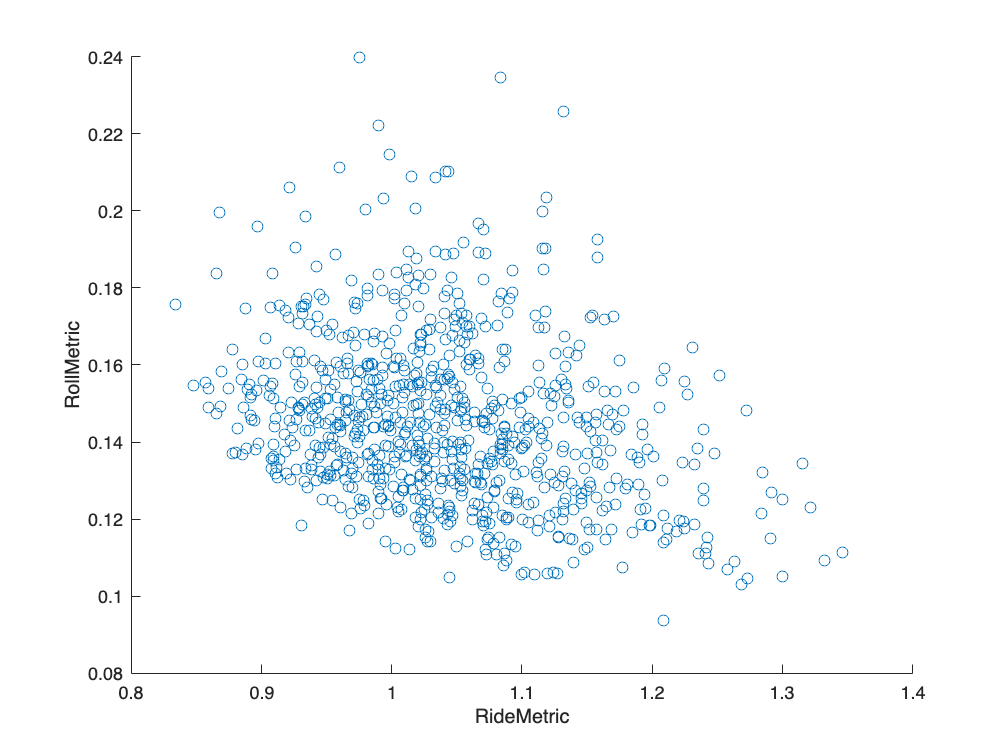

figure;
scatter(dataTable,responseVars(1),responseVars(2))

### Plot Correlation of Inputs to Responses

#### Plot data in a scatter plot

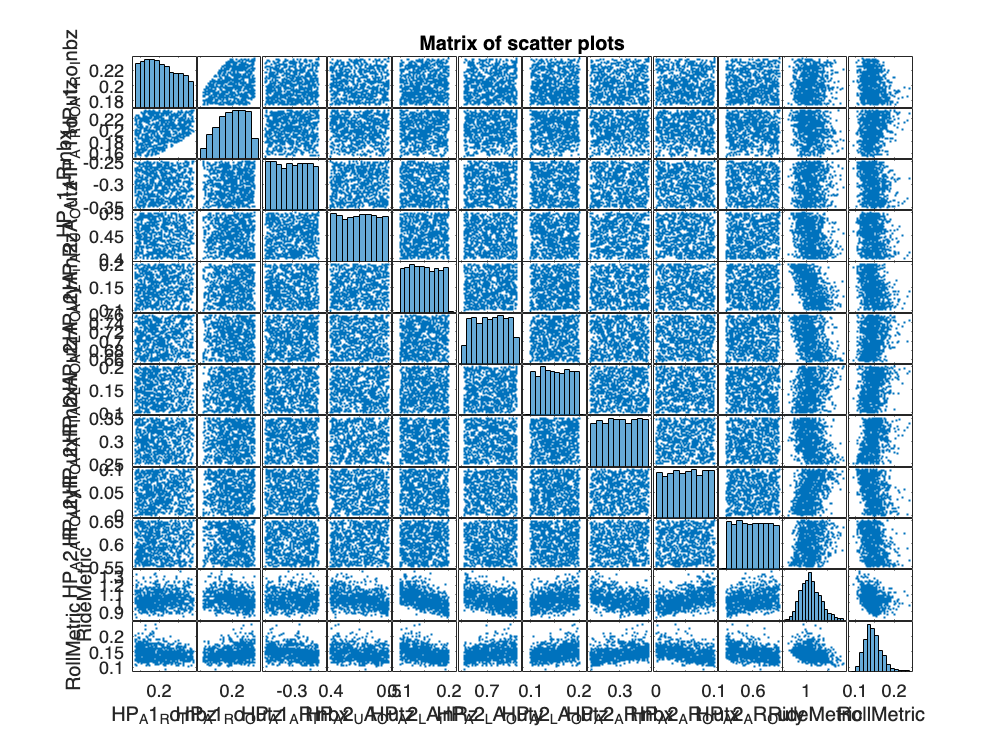

figure;
gplotmatrix(dataTable{:,:},[],[],[],[],[],[],[],...
    dataTable.Properties.VariableNames, dataTable.Properties.VariableNames)
title('Matrix of scatter plots')

#### Correlation Heatmap

Show the correlation between the inputs and the responses.  

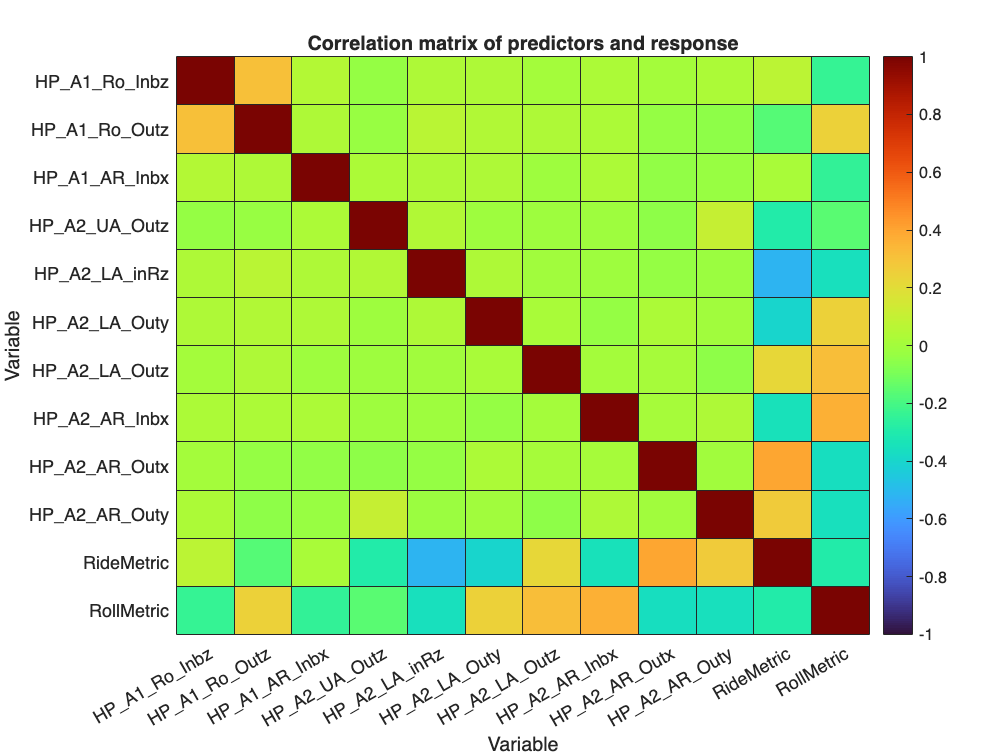

% Visualize the correlation between signals for predictors and responses
useColormap = turbo;
dataCorr = corr(dataTable{:,:});
figure;
h = heatmap(dataTable.Properties.VariableNames, dataTable.Properties.VariableNames,dataCorr,Colormap=useColormap,Interpreter="none");
clim([-1,1]);
xlabel("Variable");
ylabel("Variable");
title("Correlation matrix of predictors and response");

Another view is looking at the absolute value of correlation

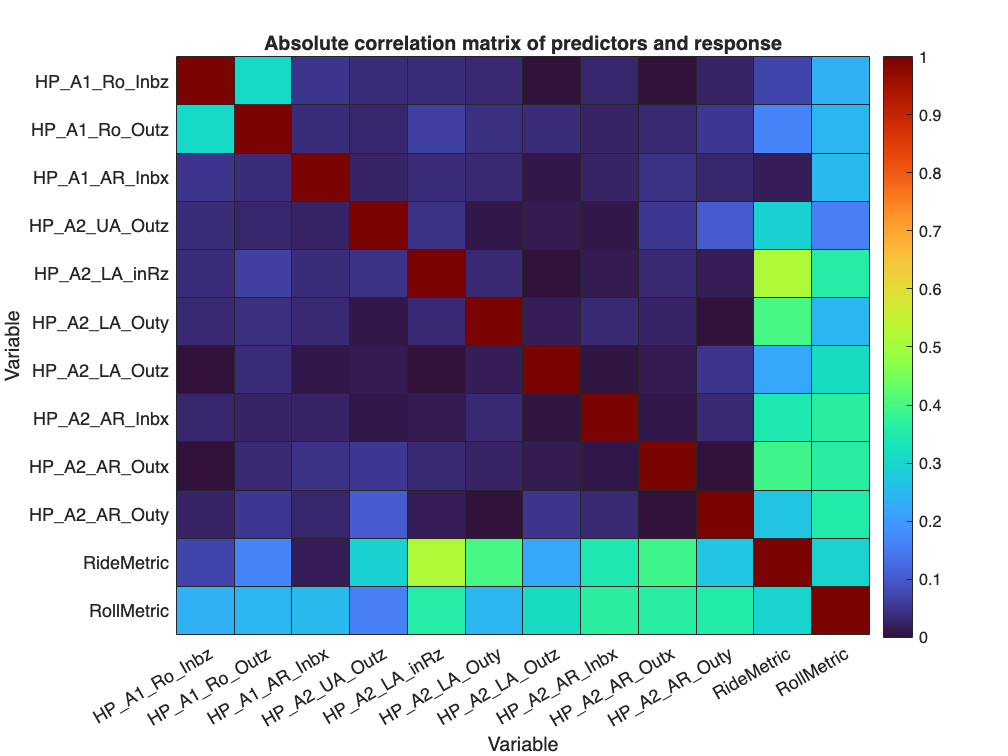

figure;
h = heatmap(dataTable.Properties.VariableNames, dataTable.Properties.VariableNames,abs(dataCorr),Colormap=useColormap,Interpreter="none");
clim([0,1]);
xlabel("Variable");
ylabel("Variable");
title("Absolute correlation matrix of predictors and response");

Plot in horizontal bar chart

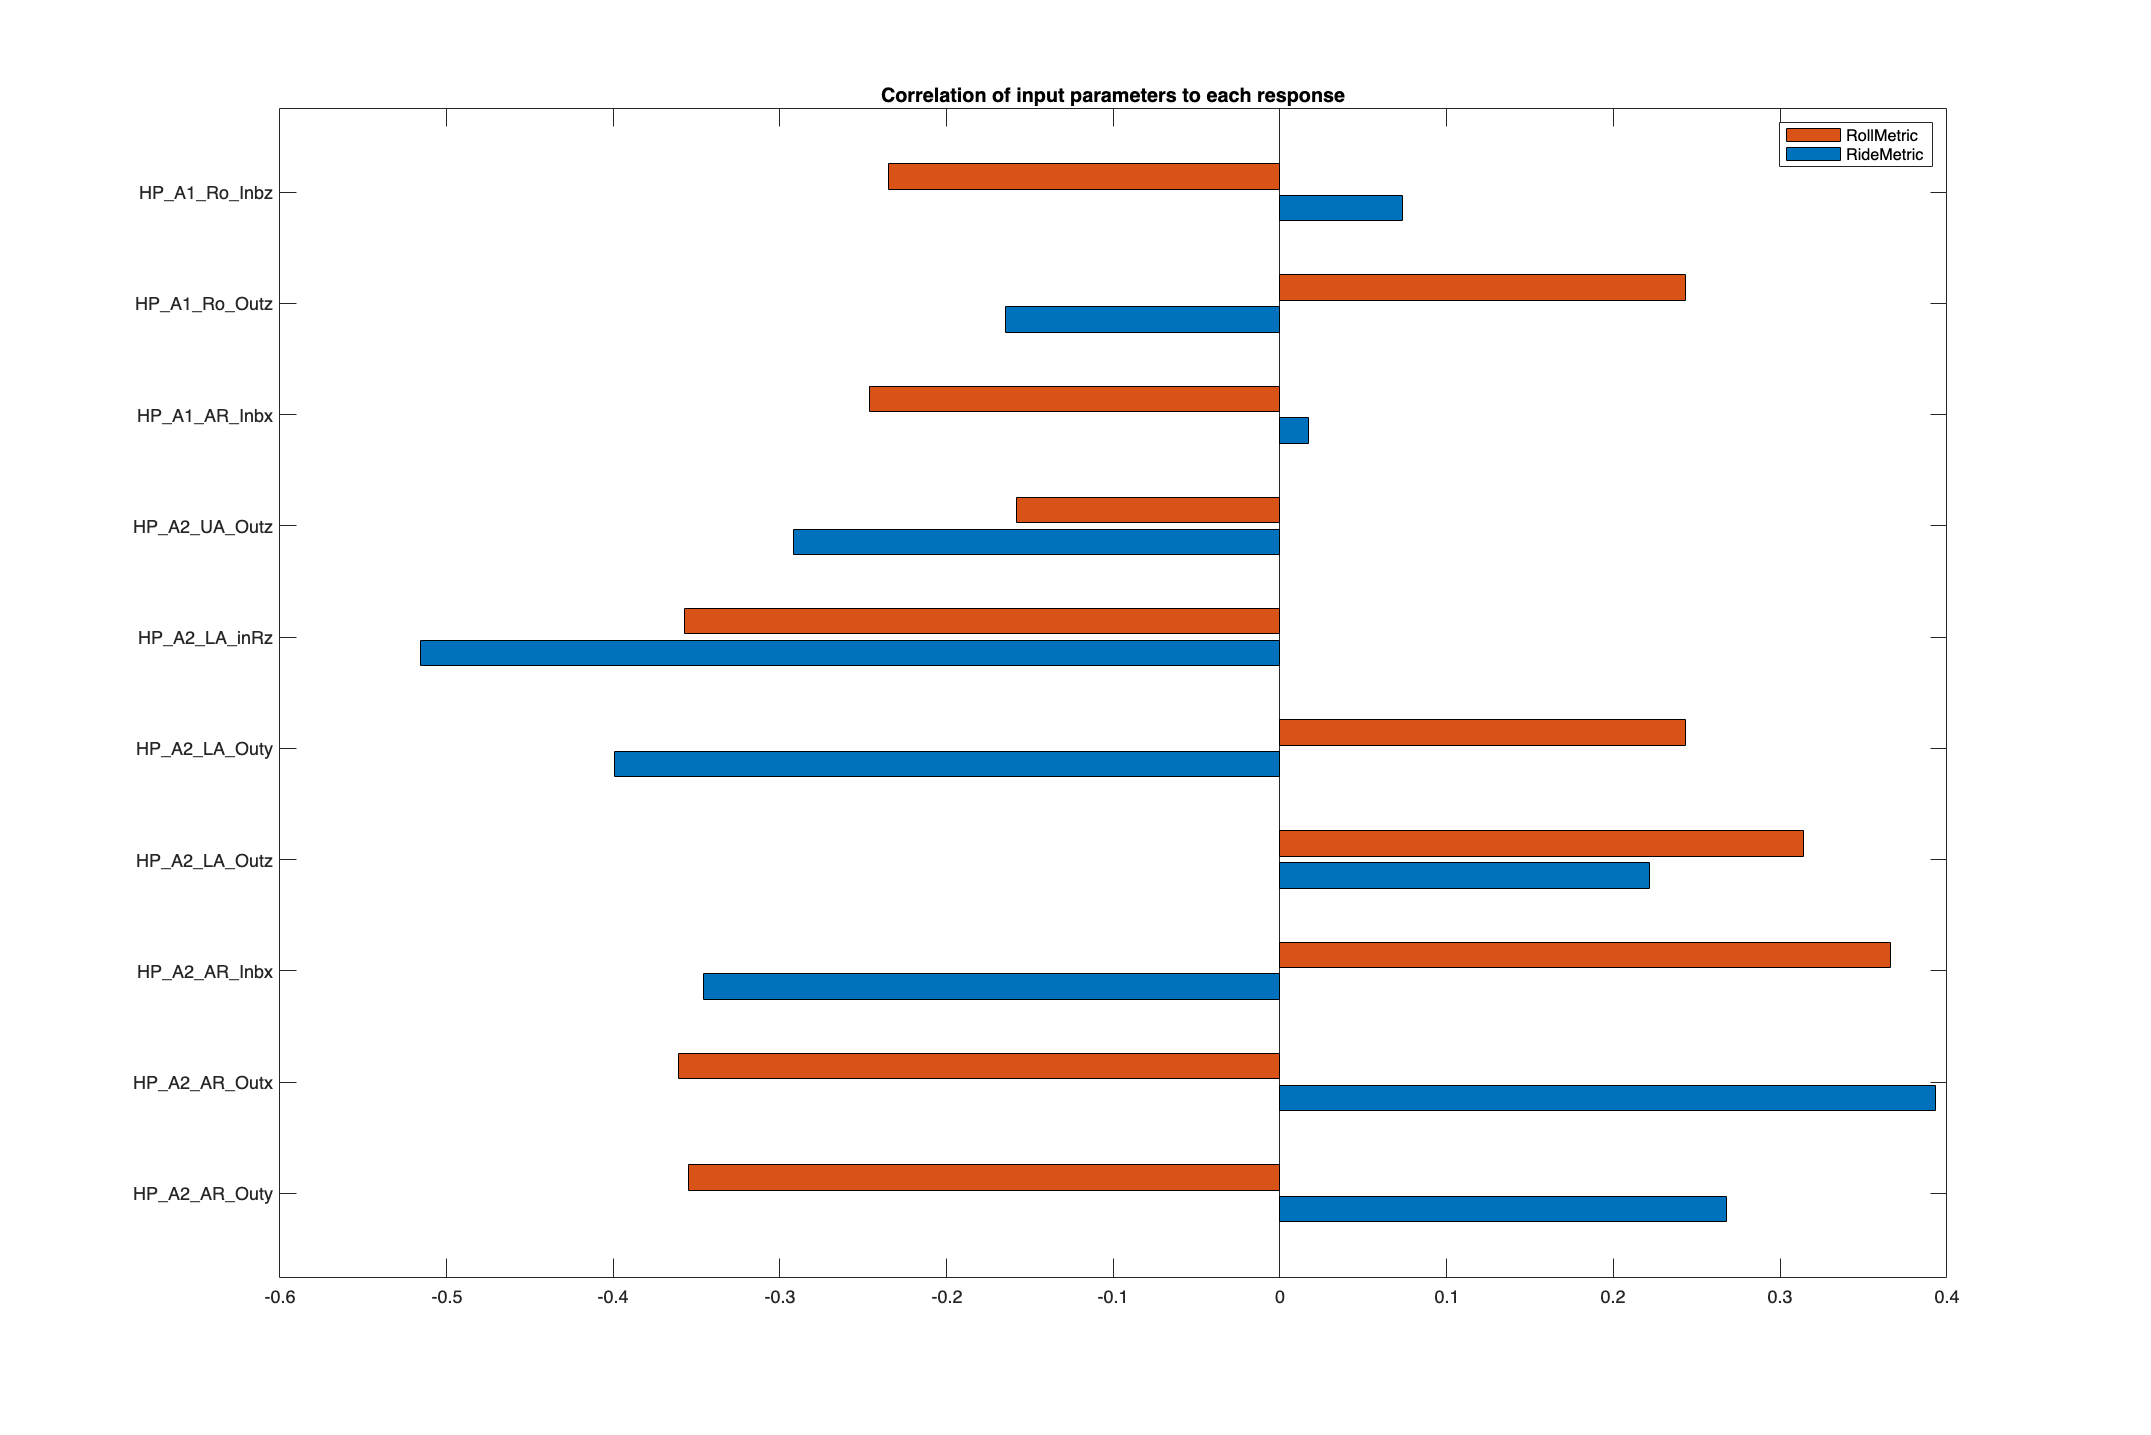

names = inputVars(end:-1:1); % Reverse order so first variable is on the top
values = dataCorr(end-1:end,end-2:-1:1);
figure(Position=[0 0 1200 800]);
barh(names,values);
title("Correlation of input parameters to each response");
set(gca,'TickLabelInterpreter','none')
legend(responseVars)

### Plot Feature Contributions using MRMR method

Next, rank features for regression using minimum redundancy maximum relevance (MRMR) algorithm.  

"The MRMR algorithm finds an optimal set of features that is mutually and maximally dissimilar and can represent the response variable effectively. The algorithm minimizes the redundancy of a feature set and maximizes the relevance of a feature set to the response variable. The algorithm quantifies the redundancy and relevance using the mutual information of variables—pairwise mutual information of features and mutual information of a feature and the response." -- see fsrmrmr() documentation.

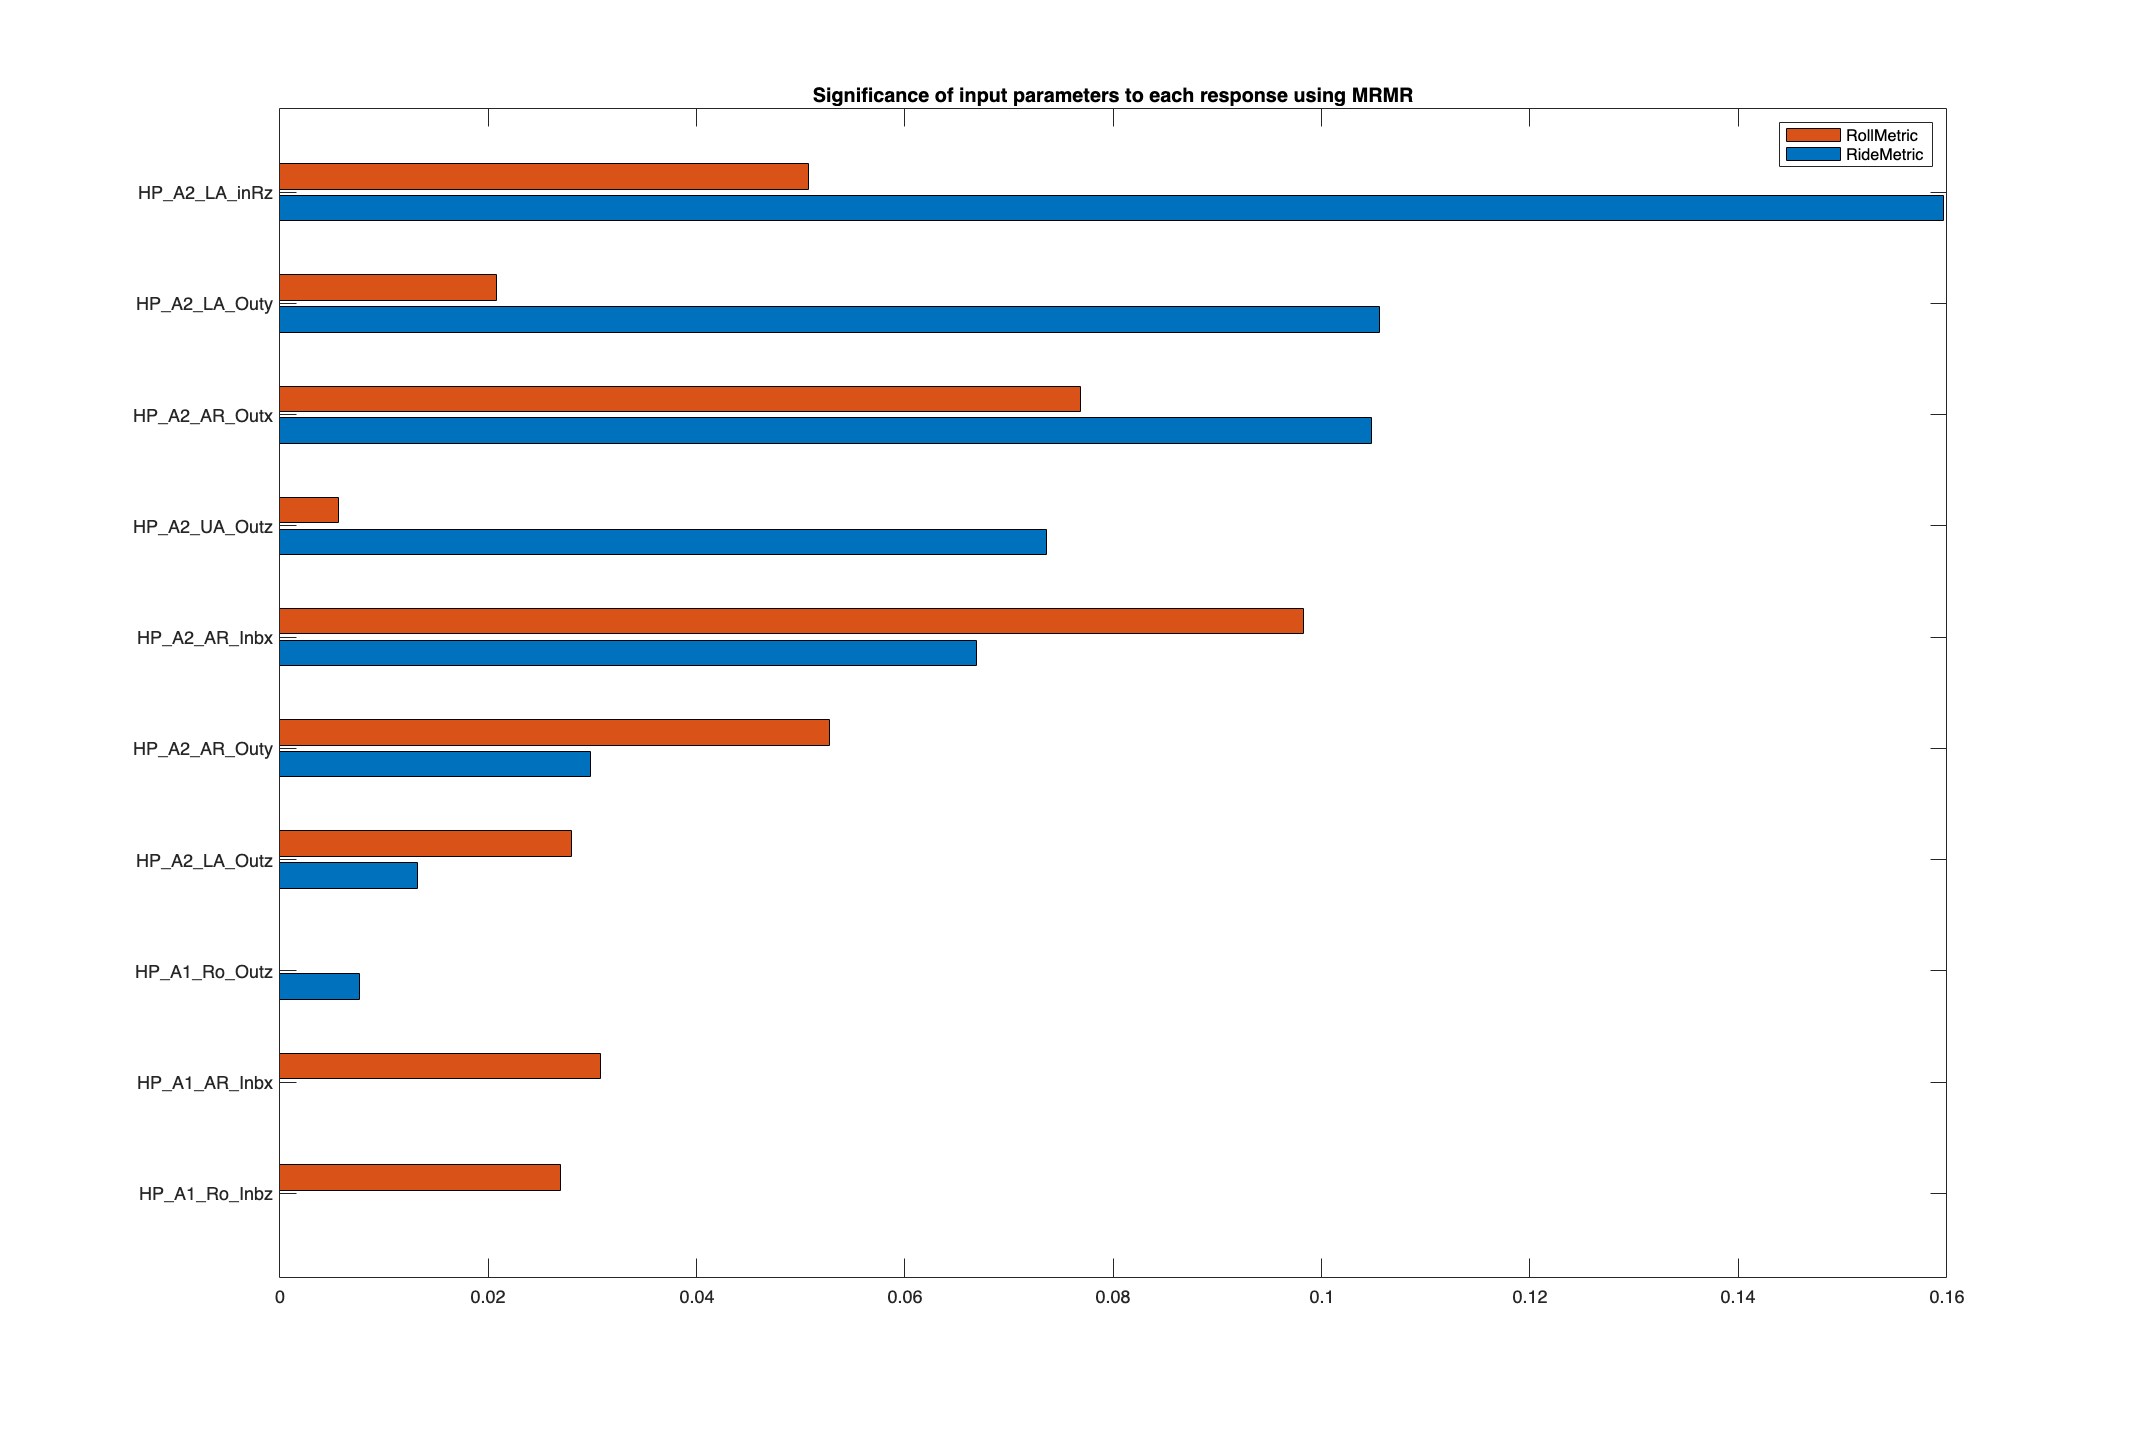

% Rank features using MRMR algorithm for each response, sorted by ranking for first response
normalizedPredictors = standardizeMissing(dataTable(:,1:end-2),{Inf, -Inf});
normalizedPredictors = normalize(normalizedPredictors);
[featureIndex, scores1] = fsrmrmr(normalizedPredictors, dataTable.(responseVars(1)));
sortedFeatureNames = string(dataTable.Properties.VariableNames(featureIndex));
[~, scores2] = fsrmrmr(normalizedPredictors, dataTable.(responseVars(2)));
scores = [scores1; scores2];

% Plot in horizontal bar chart, in reverse order
names = sortedFeatureNames(end:-1:1);
values = scores(:,featureIndex(end:-1:1));
figure(Position=[0 0 1200 800]);
barh(names,values);
title("Significance of input parameters to each response using MRMR");
set(gca,'TickLabelInterpreter','none')
legend(responseVars)

## Part 3. Train AI models (Tree Ensemble, Gaussian Process Regression, Neural Network)

This section allows you to train three different types of machine learning methods:

- Bagged ensemble of trees ("bag") - Statistics and Machine Learning Toolbox

- Gaussian process regression ("gp") - Statistics and Machine Learning Toolbox

- Deep neural network - Deep Learning Toolbox

### Machine learning models

Starting in R2024b, there are options to build multi-input, multi-output (mimo) regression models in Statistics and Machine Learning Toolbox.

If you are in R2024a or earlier, the models will need to be trained separately.

v = 'R2024b';
if isMATLABReleaseOlderThan(v) % release date for R2024b
    mimo = false; % train models separately
else
    mimo = true;
end
if mimo % R2024b or later
    gpModel  = fitrchains(trainingTable,trainingTable.Properties.VariableNames(end-1:end),Learner='gp',ChainPredictedResponse=true);
    bagModel = fitrchains(trainingTable,trainingTable.Properties.VariableNames(end-1:end),Learner='bag',ChainPredictedResponse=true);
else % R2024a or earlier
    template = templateTree('MinLeafSize', 16, 'NumVariablesToSample', 'all', 'Surrogate','on');
    rInputValues = trainingTable(:,1:end-3);
    bagModel1 = fitrensemble(rInputValues,trainingTable.(responseVars(1)),'Method', 'Bag','NumLearningCycles', 100, 'Learners', template);
    bagModel2 = fitrensemble(rInputValues,trainingTable.(responseVars(2)),'Method', 'Bag','NumLearningCycles', 100, 'Learners', template);

    gpModel1 = fitrgp(rInputValues,trainingTable.(responseVars(1)),'BasisFunction','constant','KernelFunction','rationalquadratic','Standardize', true);
    gpModel2 = fitrgp(rInputValues,trainingTable.(responseVars(2)),'BasisFunction','constant','KernelFunction','rationalquadratic','Standardize', true);
end

### Deep neural network

Define network architecture

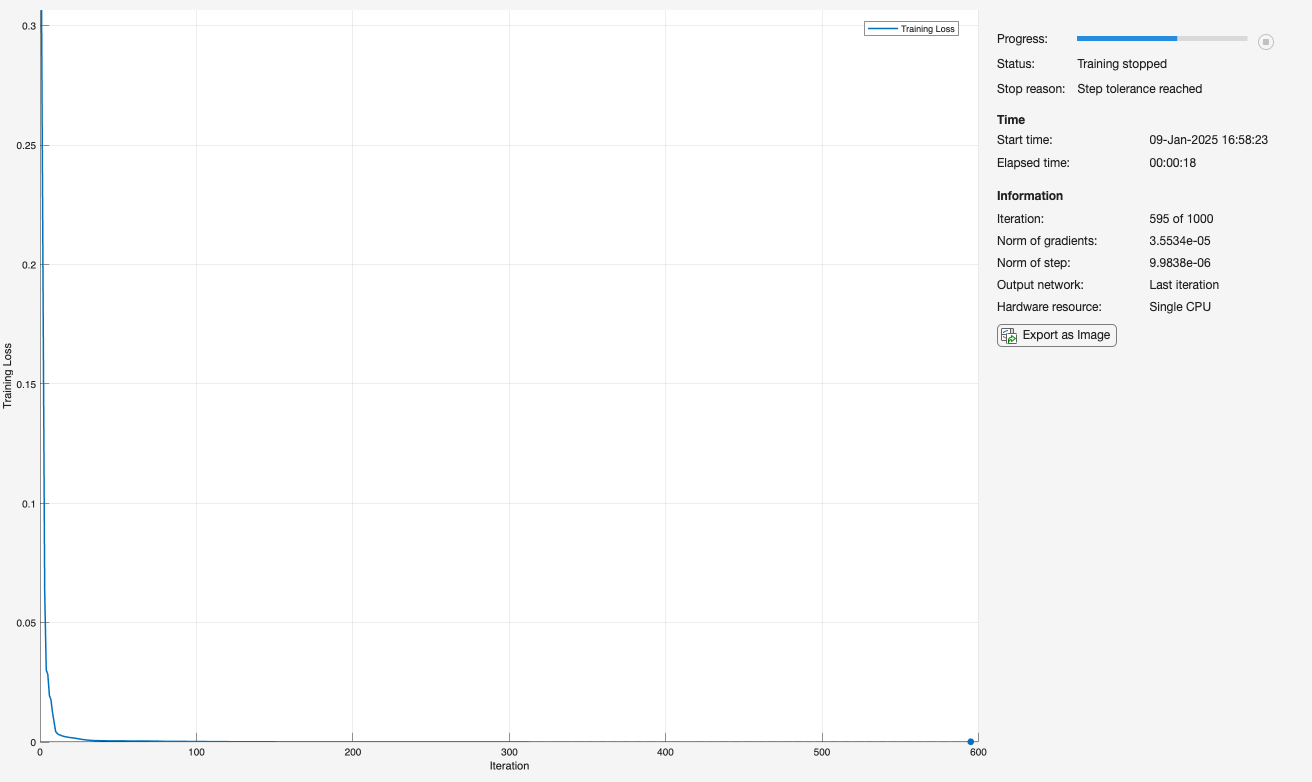

if status_dl % This will only execute if a license is present for Deep Learning Toolbox
    layers = [
        featureInputLayer(numInputs,Normalization="zscore")
        fullyConnectedLayer(16) % the number can be changed based on expert knowledge, trial-and-error, or with hyperparameter tuning
        layerNormalizationLayer
        reluLayer
        fullyConnectedLayer(numResponses)];

Specify training options

    options = trainingOptions("lbfgs", ... % try different solvers
        ExecutionEnvironment="cpu", ...
        Plots="training-progress", ...
        Verbose=false);

Train network

    nnModel = trainnet(XTrain,TTrain,layers,"mse",options);
end

## Part 4: Compute predictions on the test dataset

Do this for all three models (GP, tree, NN) and for both response variables

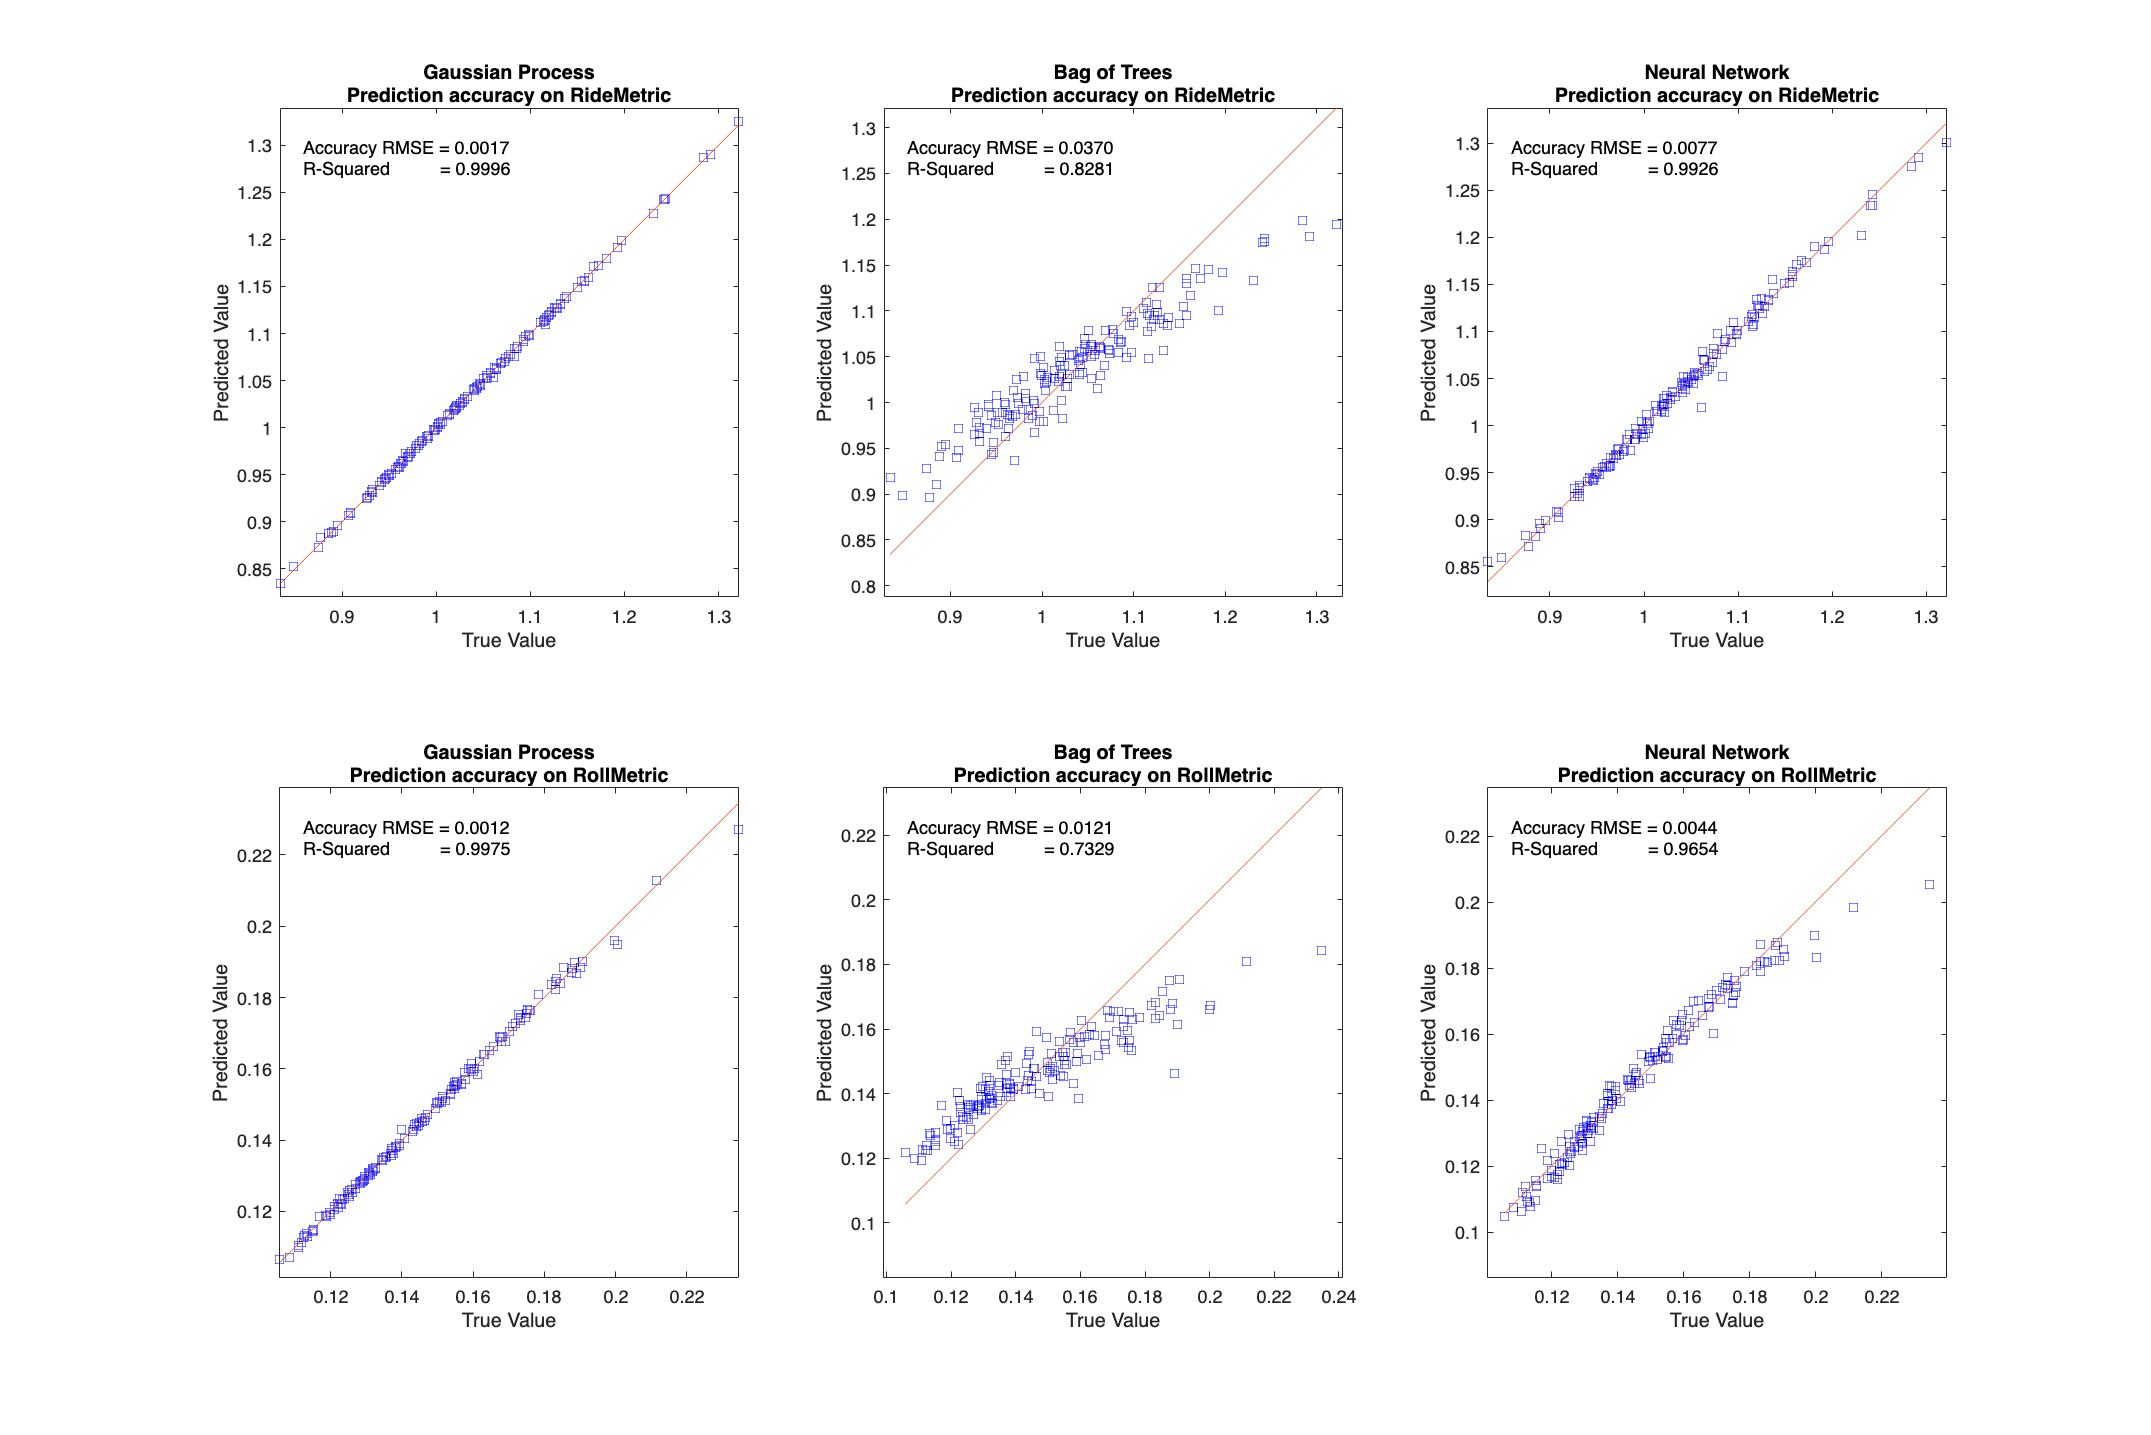

if mimo
    ypred_gp   = predict(gpModel,testTable);
    ypred_bag  = predict(bagModel,testTable);
else
    ypred_gp(:,1) = predict(gpModel1,testTable);
    ypred_gp(:,2) = predict(gpModel2,testTable);
    ypred_bag(:,1) = predict(bagModel1,testTable);
    ypred_bag(:,2) = predict(bagModel2,testTable);
end
if status_dl
    ypred_nn = minibatchpredict(nnModel,XTest);
    ypred_nn = double(ypred_nn);
end

### Calculate and plot RMSE, R-squared for all models available

resVarShort = {'rollPr';'ridePr'};                                  nr = length(resVarShort);
modelNames  = {'Gaussian Process','Bag of Trees','Neural Network'}; nm = length(modelNames);
s = struct;
for i = 1:numResponses
    responseName  = responseVars(i);
    ytruth        = TTest(:,i);
    subplot(nr,nm,nm*i-2)
    [s.(resVarShort{i}).acc.gp, s.(resVarShort{i}).rSq.gp] = verif_stats_plot(ypred_gp(:,i),ytruth,modelNames{1},responseName); hold on;
    subplot(nr,nm,nm*i-1)
    [s.(resVarShort{i}).acc.tree, s.(resVarShort{i}).rSq.tree] = verif_stats_plot(ypred_bag(:,i),ytruth,modelNames{2},responseName); hold on;
    if status_dl
        subplot(nr,nm,nm*i)
        [s.(resVarShort{i}).acc.nn, s.(resVarShort{i}).rSq.nn] = verif_stats_plot(ypred_nn(:,i),ytruth, modelNames{3},responseName); hold on;
    end
end
rollPr = s.rollPr;
ridePr = s.ridePr;

### Compare Accuracy of AI Surrogate models

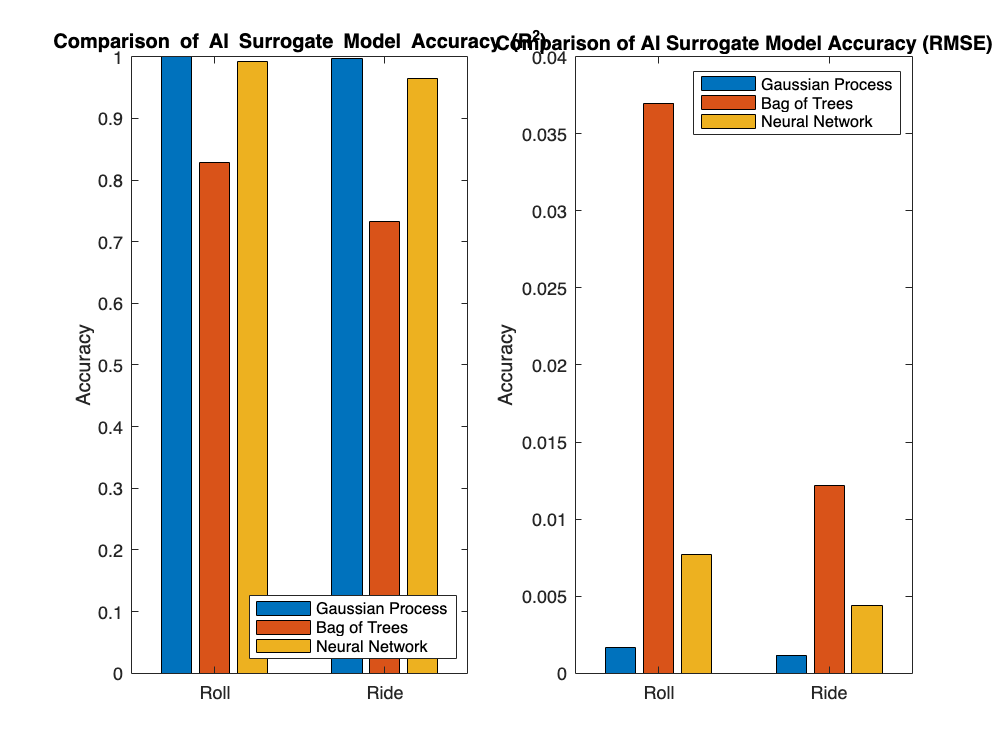

figure
% R-squared
subplot(1,2,1)

bar([struct2array(rollPr.rSq);struct2array(ridePr.rSq)]);
ax = gca;
ax.XTickLabel = {'Roll','Ride'};
ylabel('Accuracy')
legend(modelNames,'Location','SouthEast');
title('Comparison of AI Surrogate Model Accuracy (R^2)')
% RMSE
subplot(1,2,2)
bar([struct2array(rollPr.acc);struct2array(ridePr.acc)]);
ax = gca;
ax.XTickLabel = {'Roll','Ride'};
ylabel('Accuracy')
legend(modelNames,'Location','NorthEast');
title('Comparison of AI Surrogate Model Accuracy (RMSE)')

## Part 5: Save models to use for optimization workflow

aiModels = struct();
if mimo
    aiModels.gpModel  = gpModel;
    aiModels.bagModel = bagModel;
else
    aiModels.gpModel1  = gpModel1;
    aiModels.gpModel2  = gpModel2;
    aiModels.bagModel1 = bagModel1;
    aiModels.bagModel2 = bagModel2;
end
aiModels.nnModel = nnModel;

save('aiModels.mat','aiModels','trainingTable','responseVars','rollPr','ridePr');